addpath 'C:\Users\eliot\AppData\Roaming\MathWorks\MATLAB Add-Ons\Collections\FieldTrip';
ft_defaults;

-------------------------------------------------------------------------------------------
FieldTrip is developed by members and collaborators of the Donders Institute for Brain,
Cognition and Behaviour at Radboud University, Nijmegen, the Netherlands.

                          --------------------------
                        /                            \
                     ------------------------------------
                    /                                    \
          -------------------------------------------------
         /                            /\/\/\/\/\ 
         ---------------------------------------------------
                  |        F  i  e  l  d  T  r  i  p       |
                  ------------------------------------------
                   \                                      /
                     ------------------------------------
                          \            /
                            ----------

Please cite the FieldTrip re


%loading data and some relevant values

datapath='C:\Users\eliot\OneDrive\Documents\Stage\Code\tests\105_NN\EEG\105_NN_Sommeil.edf'; %Path to the datas in an edf file
scorpath="C:\Users\eliot\OneDrive\Documents\Stage\Code\tests\105_NN\105_NN_Sommeil_scores.csv"; %Path to the scoring csv file

sf=1000; %sample frequency of the signal
order=4; %Order of the filter we will apply on the datas
fcutlow=0.1; %Low born of the bandpass filter we'll apply on the datas
fcuthigh=3; %High born of the bandpass filter we'll apply on the datas


% define trials
cfg            = [];
cfg.dataset    = datapath;
cfg.continuous = 'yes';
cfg.channel    = [8 9];

cfg.bpfilter = 'yes';
cfg.bpfreq = [fcutlow fcuthigh];
cfg.bpfiltord     = order/2;

dataset           = ft_preprocessing(cfg);

processing channel { 'EOG 1' 'EOG 2' }
reading and preprocessing
reading and preprocessing trial 1 from 1

the call to "ft_preprocessing" took 42 seconds



%Dealing with the scoring

[indexes_start, indexes_end]=indexes_scor(scorpath,sf);

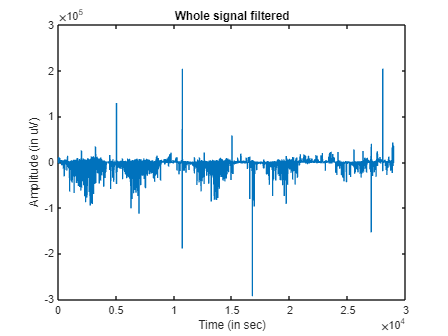



neg_p= - dataset.trial{1}(1,:) .* dataset.trial{1}(2,:);

% display the whole bipolar signal
figure()
plot(dataset.time{1},neg_p)
xlabel('Time (in sec)')
ylabel('Amplitude (in uV)')
title('Whole signal filtered')

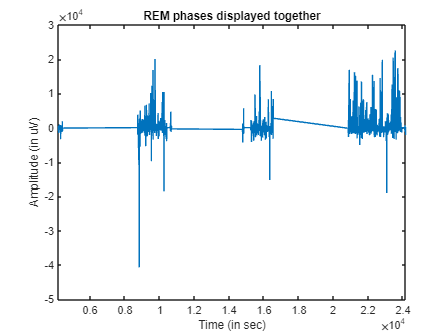



%Take only the REM phases of the  bipolar datas
[times, REM_only_f]=isolate_REM(indexes_start,indexes_end,neg_p,dataset.time);

% [times, REM_only_f] = isolate_from_scoring(scorpath,sf,neg_p)

%display that
figure()
plot(times, REM_only_f)
title('REM phases displayed together')
xlabel('Time (in sec)')
ylabel('Amplitude (in uV)')
xlim([times(1), times(length(times))])

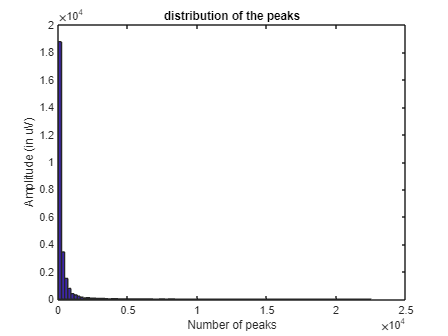

%  find peaks of the REM phase only. Implement as a function ?

abs_signal=abs(REM_only_f);
[pks, locs] = findpeaks(abs_signal);

pks(pks>= 25000)=[]; %remove the outliers where the amplitude of the signal is too high (500 uV --> 25000 in bipolar ?)

hist(pks,100)
title('distribution of the peaks')
xlabel('Number of peaks')
ylabel('Amplitude (in uV)')

%Gaussian model on the peaks
GMModel= fitgmdist(transpose(pks), 2)

GMModel = 

Gaussian mixture distribution with 2 components in 1 dimensions
Component 1:
Mixing proportion: 0.808380
Mean:   96.8834

Component 2:
Mixing proportion: 0.191620
Mean:   1.4632e+03





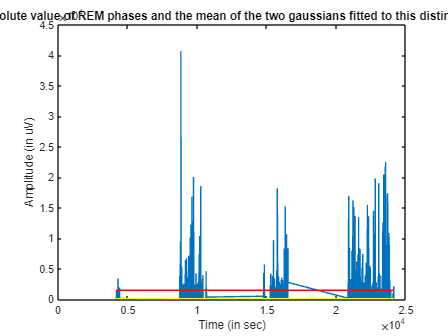


plotmu1=[max(GMModel.mu),max(GMModel.mu)];
plottmu1=[times(1),times(length(times))];
plotmu2=[min(GMModel.mu),min(GMModel.mu)];
plottmu2=[times(1),times(length(times))];


%plotting
figure()
% plot(dataset.time{1}(1,indexes_start(7)*30000:indexes_end(7)*30000),abs(neg_p(1,indexes_start(7)*30000:indexes_end(7)*30000)))
plot(times, abs_signal)

hold on 
plot(plottmu1, plotmu1, 'r')
plot(plottmu2,plotmu2, 'y')
title('Absolute value of REM phases and the mean of the two gaussians fitted to this distiribution');
xlabel('Time (in sec)')
ylabel('Amplitude (in uV)')
hold off

threshold_tmp=max(GMModel.mu);  %THRESHOLD WE DEFINE AND CHOOSE TO USE TO DEFINE THE REM PARTS
potential_EM= abs_signal;
timep=times;
timep(potential_EM<=threshold_tmp)=[];
potential_EM(potential_EM<=threshold_tmp)=[];



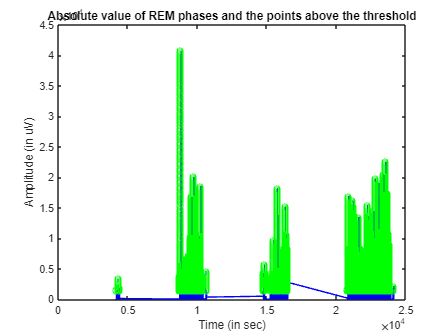

plot(times, abs_signal,'b')
title('Absolute value of REM phases and the points above the threshold');
xlabel('Time (in sec)')
ylabel('Amplitude (in uV)')
hold on
plot(timep, potential_EM,'go')
hold off

% zc=times(potential_EM<20);
% % potential_EM= potential_EM-threshold_tmp;
% 
% UpZCi = @(v) find(v(1:end-1) <= threshold_tmp+20 & v(2:end) > threshold_tmp+20);	% Returns Up Zero-Crossing Indices
% DownZCi = @(v) find(v(1:end-1) >= threshold_tmp+20 & v(2:end) <threshold_tmp+20 );    % Returns Down Zero-Crossing Indices
% 
% UpZCiv=UpZCi(potential_EM);
% DownZCiv=DownZCi(potential_EM);

ans = 'content'

ans = 'content'

Index exceeds the number of array elements. Index must not exceed 806.


derivee=diff(potential_EM)/(timep(2)-timep(1));



Error using plot
Vectors must be the same length.